clc;
clear;
close all;
%load data
map = load('map.txt');
path = load('path.txt');
formation_path = load('fpath.txt');

path1=formation_path(1:4:end,:);
path2=formation_path(2:4:end,:);
path3=formation_path(3:4:end,:);
path4=formation_path(4:4:end,:);

teb1 = load('traj1.txt');
teb2 = load('traj2.txt');
teb3 = load('traj3.txt');
teb4 = load('traj4.txt');


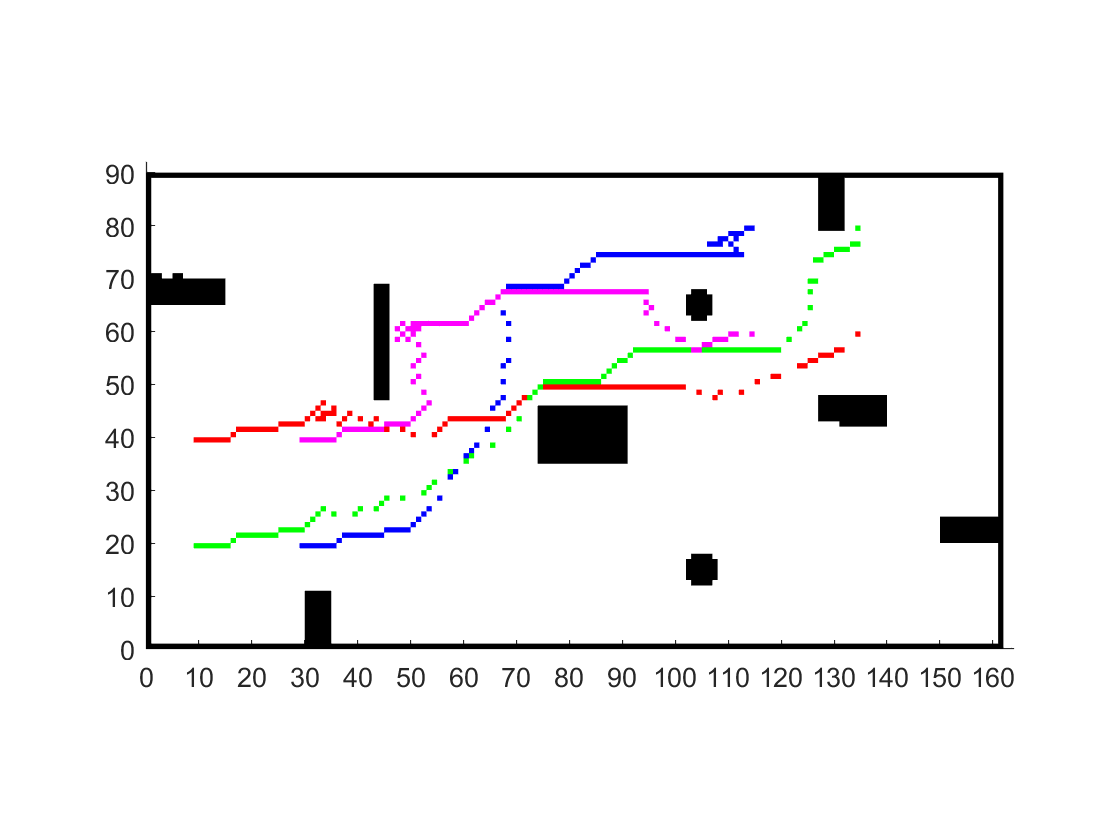


figure("Name","地图");
a=size(map,1);
b=size(map,2);
axes('GridLineStyle',"none",'GridAlpha',0.8);
axis equal;

hold on;
grid on;
axis([0,a+2,0,b+2]);
set(gca,'xtick',0:10:a+2,'ytick',0:10:b+2);

obs = zeros(1,2);

%找到障碍物
for i=1:a
    for j=1:b
        if(~map(i,j)) 
                obs(end+1, :) = [i,j];
                hold on;
        end
    end
end

% 绘制障碍物
for i = 1 : size(obs, 1)
    temp = obs(i, :);
    fill([temp(1)-1, temp(1), temp(1), temp(1)-1],...
        [temp(2)-1, temp(2)-1, temp(2), temp(2)], 'k', 'handlevisibility', 'off','EdgeColor',"none");
end
% 绘制路径
for i = 1 : size(path1, 1)
    temp = path1(i, :);
    fill([temp(1)-1, temp(1), temp(1), temp(1)-1],...
        [temp(2)-1, temp(2)-1, temp(2), temp(2)], 'r', 'handlevisibility', 'off','EdgeColor',"none");
end
for i = 1 : size(path2, 1)
    temp = path2(i, :);
    fill([temp(1)-1, temp(1), temp(1), temp(1)-1],...
        [temp(2)-1, temp(2)-1, temp(2), temp(2)], 'g', 'handlevisibility', 'off','EdgeColor',"none");
end
for i = 1 : size(path3, 1)
    temp = path3(i, :);
    fill([temp(1)-1, temp(1), temp(1), temp(1)-1],...
        [temp(2)-1, temp(2)-1, temp(2), temp(2)], 'b', 'handlevisibility', 'off','EdgeColor',"none");
end
for i = 1 : size(path4, 1)
    temp = path4(i, :);
    fill([temp(1)-1, temp(1), temp(1), temp(1)-1],...
        [temp(2)-1, temp(2)-1, temp(2), temp(2)], 'm', 'handlevisibility', 'off','EdgeColor',"none");
end

i = 1

i = 20

i = 50

i = 90

i = 106

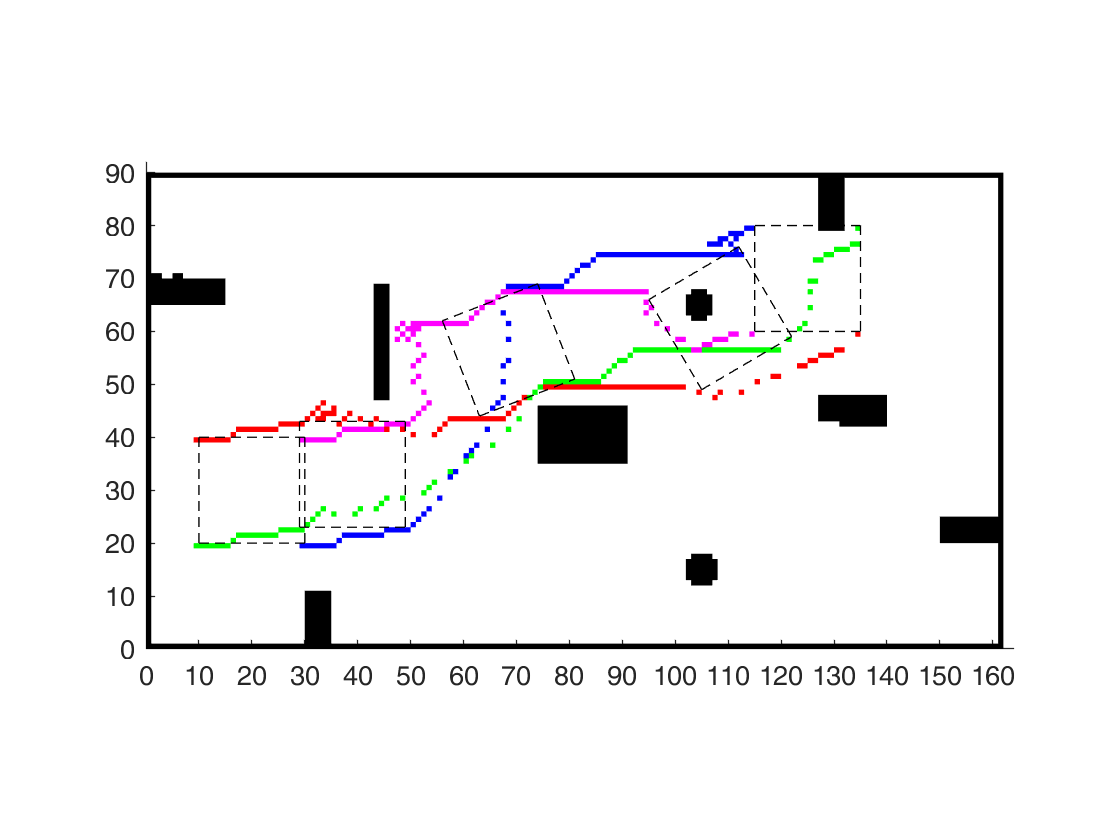

% %% rect
line_index =[1,20,50,90,size(path1,1)];
for index=1:size(line_index, 2)
    i = line_index(index)
    line([path1(i,1), path2(i,1)],[path1(i,2), path2(i,2)],'color',[0,0,0],'LineStyle','--');%1-2
    line([path2(i,1), path3(i,1)],[path2(i,2), path3(i,2)],'color',[0,0,0],'LineStyle','--');%2-3
    line([path3(i,1), path4(i,1)],[path3(i,2), path4(i,2)],'color',[0,0,0],'LineStyle','--');%3-4
    line([path4(i,1), path1(i,1)],[path4(i,2), path1(i,2)],'color',[0,0,0],'LineStyle','--');%4-1
end


%% tri
% line_index =[1,20,50,80,90,size(path1,1)];
% for index=1:size(line_index, 2)
%     i = line_index(index)
%     line([path1(i,1), path2(i,1)],[path1(i,2), path2(i,2)],'color',[0,0,0],'LineStyle','--');%1-2
%     line([path2(i,1), path3(i,1)],[path2(i,2), path3(i,2)],'color',[0,0,0],'LineStyle','--');%2-3
%     line([path3(i,1), path1(i,1)],[path3(i,2), path1(i,2)],'color',[0,0,0],'LineStyle','--');%3-1
%     line([path1(i,1), path4(i,1)],[path1(i,2), path4(i,2)],'color',[0,0,0],'LineStyle','--');%1-4
%     line([path2(i,1), path4(i,1)],[path2(i,2), path4(i,2)],'color',[0,0,0],'LineStyle','--');%2-4
%     line([path3(i,1), path4(i,1)],[path3(i,2), path4(i,2)],'color',[0,0,0],'LineStyle','--');%3-4
%     
% end
%%line
% line_index =[1,20,50,80,90,size(path1,1)];
% for index=1:size(line_index, 2)
%     i = line_index(index)
%     line([path1(i,1), path2(i,1)],[path1(i,2), path2(i,2)],'color',[0,0,0],'LineWidth',1,'LineStyle','--');%1-2
%     line([path2(i,1), path3(i,1)],[path2(i,2), path3(i,2)],'color',[0,0,0],'LineWidth',1,'LineStyle','--');%2-3
%     line([path3(i,1), path4(i,1)],[path3(i,2), path4(i,2)],'color',[0,0,0],'LineWidth',1,'LineStyle','--');%3-4
% end

%%画出轨迹图
N = size(teb1,1)

N = 28

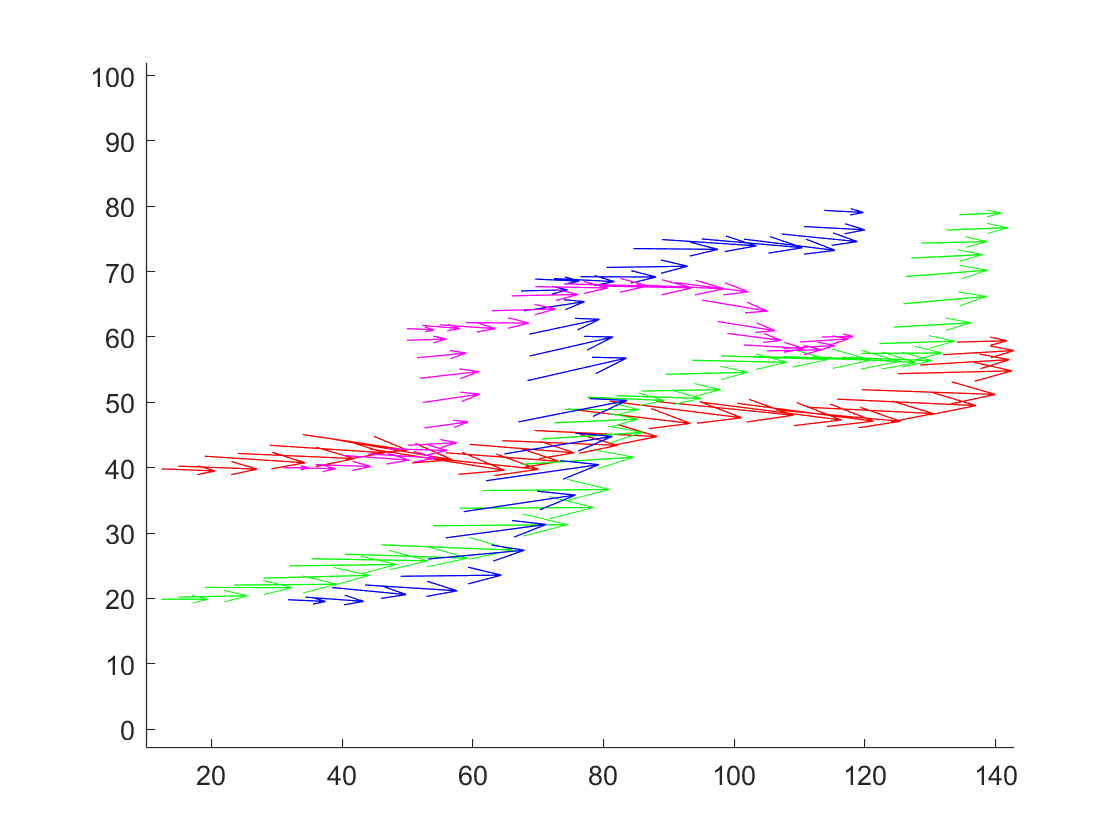

figure();
hold on;
%plot(teb1(1,1),teb1(1,2), 'g*');
%quiver(teb1(1,1),teb1(1,2),cos(teb1(1,3)),sin(teb1(1,3)),'b');
x1=teb1(:,1).*20;
y1=teb1(:,2).*20;
len1 = vecnorm(teb1(:,4:6), 2, 2);
u1=cos(teb1(:,3)).*len1;
v1=sin(teb1(:,3)).*len1;
quiver(x1,y1,u1,v1,'r');

x2=teb2(:,1).*20;
y2=teb2(:,2).*20;
len2 = vecnorm(teb2(:,4:6), 2, 2);
u2=cos(teb2(:,3)).*len2;
v2=sin(teb2(:,3)).*len2;
quiver(x2,y2,u2,v2,'g');

x3=teb3(:,1).*20;
y3=teb3(:,2).*20;
len3 = vecnorm(teb3(:,4:6), 2, 2);
u3=cos(teb3(:,3)).*len3;
v3=sin(teb3(:,3)).*len3;
quiver(x3,y3,u3,v3,'b');

x4=teb4(:,1).*20;
y4=teb4(:,2).*20;
len4 = vecnorm(teb4(:,4:6), 2, 2);
u4=cos(teb4(:,3)).*len4;
v4=sin(teb4(:,3)).*len4;
quiver(x4,y4,u4,v4,'m');

axis equal;


%     line([teb1(1,1), teb2(1,1)],[teb1(1,2), teb2(1,2)],'color',[0,0,0],'LineStyle','--');%1-2
%     line([teb2(1,1), teb3(1,1)],[teb2(1,2), teb3(1,2)],'color',[0,0,0],'LineStyle','--');%2-3
%     line([teb3(1,1), teb4(1,1)],[teb3(1,2), teb4(1,2)],'color',[0,0,0],'LineStyle','--');%3-4
%     line([teb4(1,1), teb1(1,1)],[teb4(1,2), teb1(1,2)],'color',[0,0,0],'LineStyle','--');%4-1
%     
%     line([teb1(113,1), teb2(139,1)],[teb1(113,2), teb2(139,2)],'color',[0,0,0],'LineStyle','--');%1-2
%     line([teb2(139,1), teb3(108,1)],[teb2(139,2), teb3(108,2)],'color',[0,0,0],'LineStyle','--');%2-3
%     line([teb3(108,1), teb4(96,1)],[teb3(108,2), teb4(96,2)],'color',[0,0,0],'LineStyle','--');%3-4
%     line([teb4(96,1), teb1(113,1)],[teb4(96,2), teb1(113,2)],'color',[0,0,0],'LineStyle','--');%4-1
%     
%     line([teb1(113,1), teb2(139,1)],[teb1(113,2), teb2(139,2)],'color',[0,0,0],'LineStyle','--');%1-2
%     line([teb2(139,1), teb3(108,1)],[teb2(139,2), teb3(108,2)],'color',[0,0,0],'LineStyle','--');%2-3
%     line([teb3(108,1), teb4(96,1)],[teb3(108,2), teb4(96,2)],'color',[0,0,0],'LineStyle','--');%3-4
%     line([teb4(96,1), teb1(113,1)],[teb4(96,2), teb1(113,2)],'color',[0,0,0],'LineStyle','--');%4-1
% %% rect
% line_index =[1,20,50,90,size(teb4,1)];
% for index=1:size(line_index, 2)
%     i = line_index(index)
%     line([teb1(i,1), teb2(i,1)],[teb1(i,2), teb2(i,2)],'color',[0,0,0],'LineStyle','--');%1-2
%     line([teb2(i,1), teb3(i,1)],[teb2(i,2), teb3(i,2)],'color',[0,0,0],'LineStyle','--');%2-3
%     line([teb3(i,1), teb4(i,1)],[teb3(i,2), teb4(i,2)],'color',[0,0,0],'LineStyle','--');%3-4
%     line([teb4(i,1), teb1(i,1)],[teb4(i,2), teb1(i,2)],'color',[0,0,0],'LineStyle','--');%4-1
% end

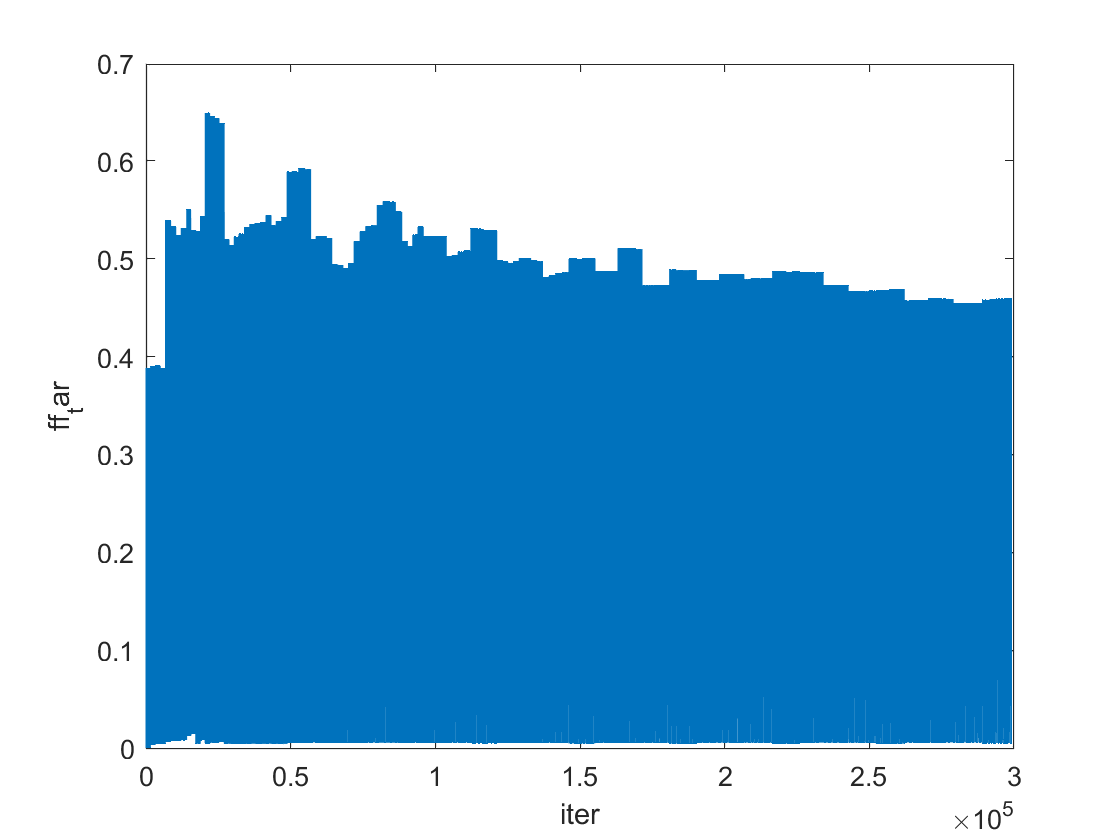

filename = 'dubug_data.txt';
maxRows = 500;  % 最大加载行数

debug_data = readmatrix(filename);

iter_traj = 1;
iter_formation = 1;
%优化期间的ff值
ff_cur=[];
ff_tar=[];
SNL0 = LaplaceMatrix([0.569669 2.0062;0.574834 0.998835; 1.58392 1.00809; 1.57148 2.00123],true);
for t = 1:length(debug_data)  
    x=debug_data(t,2);
    y=debug_data(t,3);
    x1=debug_data(t,4);
    y1=debug_data(t,5);
    
    x2=debug_data(t,6);
    y2=debug_data(t,7);
    x3=debug_data(t,8);
    y3=debug_data(t,9);
    x4=debug_data(t,10);
    y4=debug_data(t,11);
    SNL_tar = LaplaceMatrix([x1 y1;x2 y2;x3 y3;x4 y4],true);
    SNL_cur = LaplaceMatrix([x y;x2 y2;x3 y3;x4 y4],true); 
    ff_tar(end+1) = norm(SNL_tar-SNL0,"fro");
    ff_cur(end+1) = norm(SNL_cur-SNL0,"fro");
end
figure();
plot(ff_tar)
xlabel("iter");
ylabel("ff-tar");

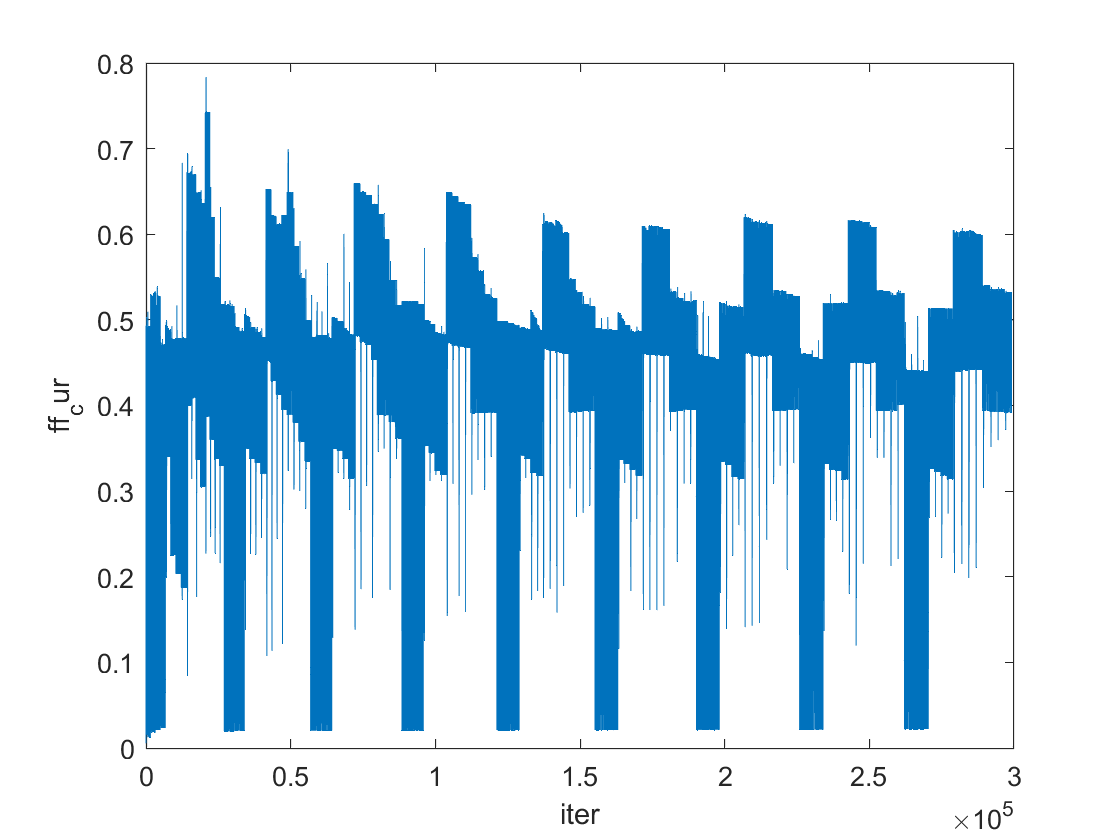


figure();
plot(ff_cur)
xlabel("iter");
ylabel("ff-cur");

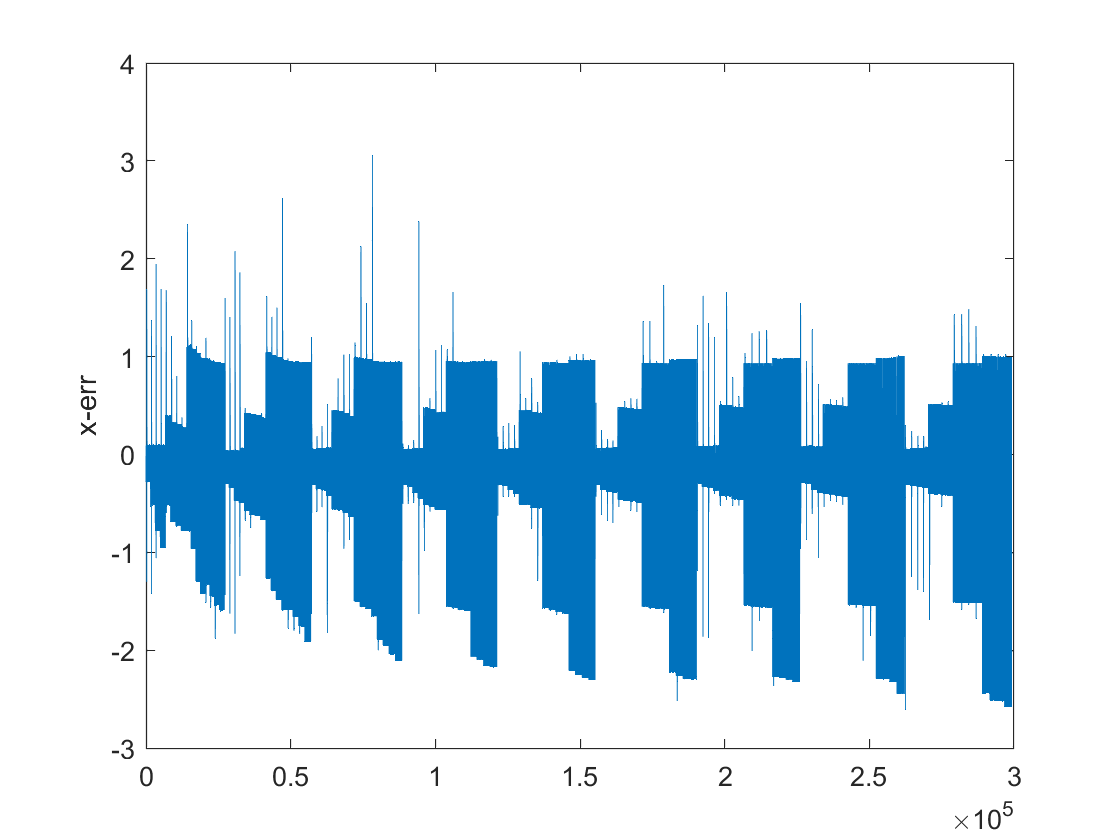



figure();
plot(debug_data(:,2)-debug_data(:,4));
ylabel("x-err");

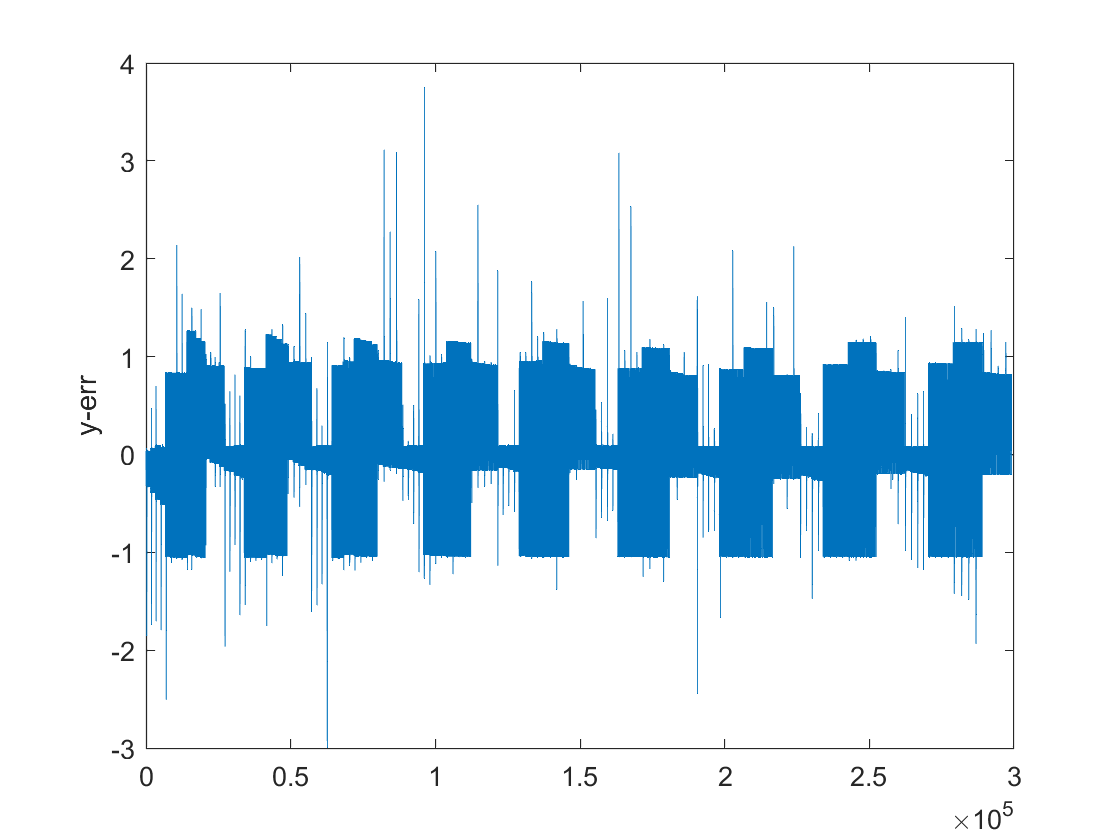

figure()
plot(debug_data(:,3)-debug_data(:,5));
ylabel("y-err");

% figure();
% plot(debug_data(debug_data(:, 1) == 1,12));

fileID = fopen('obs.txt', 'w');
fprintf(fileID, '%d %d\n', obs(:,1), obs(:,2));  % 将变量写文本文件，每个值占一行
fclose(fileID);